# Type II Regression: Errors in X and Y

There is no standard way of caculating the regression if there are uncertainties in both the X and Y measurements. One popular method is to calcualte an un-weighted least squares regression for Y as a function of X, and then an un-weighted least squares regression for X as a function of Y and take the geometric mean of the two slopes. There are other ways of estimating the fitting parameters for a Type II regression that can be found in the references listed below, though some of these techniques should be used wirh caution.

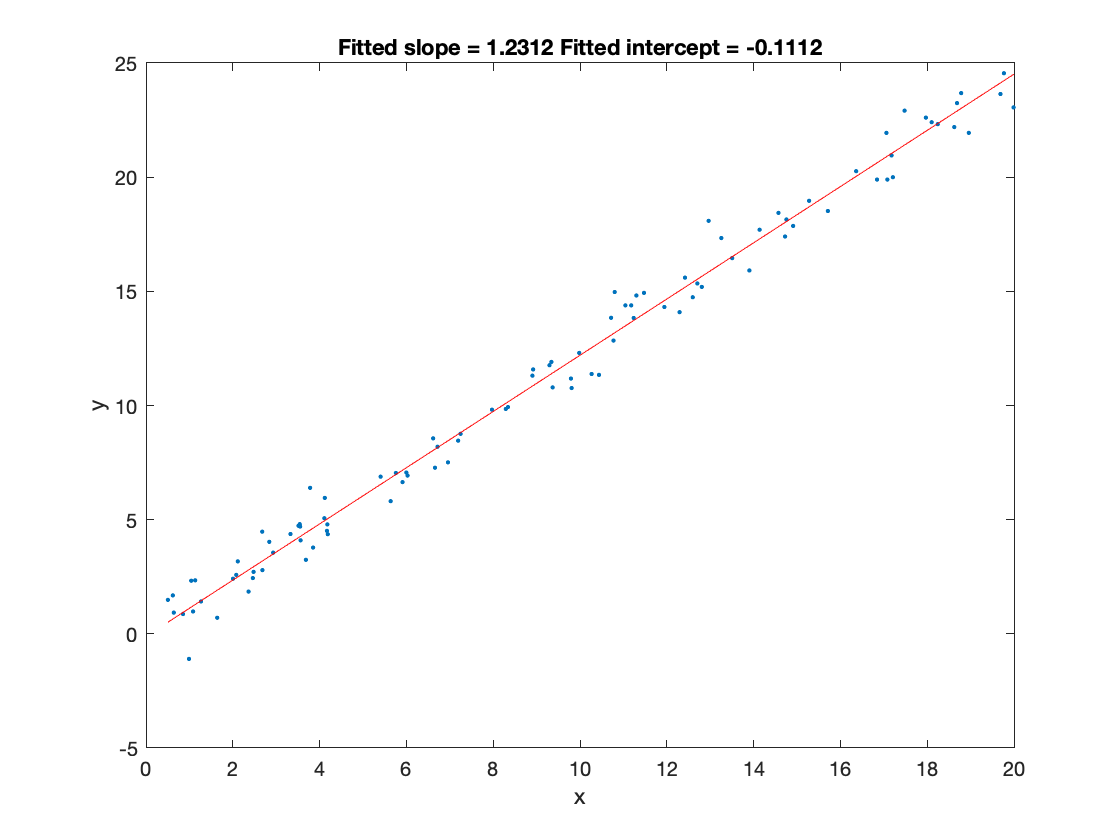

% First create some fake data

n_data = 100;

% Create the x-values that are uniformly distrbuted between x=0 and x=20
x_min = 0.0;
x_max = 20.0;

x_data = x_min + (x_max - x_min)*rand([100,1]);

% Now create a series of y values using the equation of a straight line
% with noise
slope_data     = 1.2;
intercept_data = 0.3;
std_data       = 0.8;  % Standard deviation of the noise about the data.

y_data = intercept_data + slope_data*x_data + std_data*randn([100,1]);

% Now calculate the type II regression 
[slope_fit, intercept_fit] = TypeIIRegression(x_data, y_data);

% Calculate the straight line
y_fit = intercept_fit + slope_fit*x_data;

% Plot the results
figure(1)
plot(x_data, y_data, '.', x_data, y_fit, 'r-')
xlabel('x')
ylabel('y')
title(['Fitted slope = ' num2str(slope_fit) ' Fitted intercept = ' num2str(intercept_fit)])

***Exercise:**** Investigate how well the fitted parameters agree with the ones used in creating data as the standard deviation of the noise (*`std_data`*) is varied. *

## References

Legendre P., Legendre L. (1998) *Numerical Ecology, *2nd Edition (Elsevier, Amsterdam)

Ricker W.E. (1973). Linear regression in fiheries research. Journal of the Fisheries Research Board of Canada, 30(3):409–434. 